# Sequence Classification Using 1-D Convolutions

This example shows how to classify sequence data using a 1-D convolutional neural network.

To train a deep neural network to classify sequence data, you can use a 1-D convolutional neural network. A 1-D convolutional layer learns features by applying sliding convolutional filters to 1-D input. Using 1-D convolutional layers can be faster than using recurrent layers because convolutional layers can process the input with a single operation. By contrast, recurrent layers must iterate over the time steps of the input. However, depending on the network architecture and filter sizes, 1-D convolutional layers might not perform as well as recurrent layers, which can learn long-term dependencies between time steps.

## Load Sequence Data

Load the example data from `WaveformData.mat`. The data is a `numObservations`-by-1 cell array of sequences, where `numObservations` is the number of sequences. Each sequence is a `numTimeSteps`-by`-numChannels` numeric array, where `numTimeSteps` is the number of time steps of the sequence and `numChannels` is the number of channels of the sequence.

load WaveformData

Visualize some of the sequences in a plot.

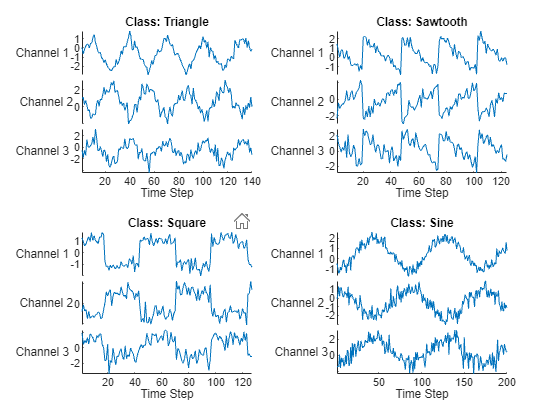

numChannels = size(data{1},2);

idx = [3 4 5 12];
figure
tiledlayout(2,2)
for i = 1:4
    nexttile
    stackedplot(data{idx(i)},DisplayLabels="Channel "+string(1:numChannels))
    
    xlabel("Time Step")
    title("Class: " + string(labels(idx(i))))
end

Set aside data for validation and testing. Partition the data into a training set containing 80% of the data, a validation set containing 10% of the data, and a test set containing the remaining 10% of the data. To partition the data, use the `trainingPartitions` function, attached to this example as a supporting file. To access this file, open the example as a live script.

numObservations = numel(data);
[idxTrain,idxValidation,idxTest] = trainingPartitions(numObservations, [0.8 0.1 0.1]);
XTrain = data(idxTrain);
TTrain = labels(idxTrain);

XValidation = data(idxValidation);
TValidation = labels(idxValidation);

XTest = data(idxTest);
TTest = labels(idxTest);

## Define 1-D Convolutional Network Architecture

Define the 1-D convolutional neural network architecture. 

- Specify the input size as the number of channels of the input data. 

- Specify two blocks of 1-D convolution, ReLU, and layer normalization layers, where the convolutional layer has a filter size of 5. Specify 32 and 64 filters for the first and second convolutional layers, respectively. For both convolutional layers, left-pad the inputs such that the outputs have the same length (causal padding).

- To reduce the output of the convolutional layers to a single vector, use a 1-D global average pooling layer.

- To map the output to a vector of probabilities, specify a fully connected layer with an output size matching the number of classes followed by a softmax layer.

filterSize = 5;
numFilters = 32;

classNames = categories(TTrain);
numClasses = numel(classNames);

layers = [ ...
    sequenceInputLayer(numChannels)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    globalAveragePooling1dLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer];

## Specify Training Options

Specify the training options. Choosing among the options requires empirical  analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:matlab_ref.mw_11ce840f-eed7-4975-9c28-baeebd79f092) app. 

- Train for 60 epochs using the Adam optimizer with a learn rate of 0.01.

- Left-pad the sequences.

- Validate the network using the validation data.

- Monitor the training progress in a plot and suppress the verbose output.

options = trainingOptions("adam", ...
    MaxEpochs=60, ...
    InitialLearnRate=0.01, ...
    SequencePaddingDirection="left", ...
    ValidationData={XValidation,TValidation}, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

## Train Neural Network

Train the neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. For classification, use cross-entropy loss. By default, the `trainnet` function uses a GPU if one is available. Training on a GPU requires a Parallel  Computing Toolbox™ license and a supported GPU device. For information  on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the `trainnet` function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

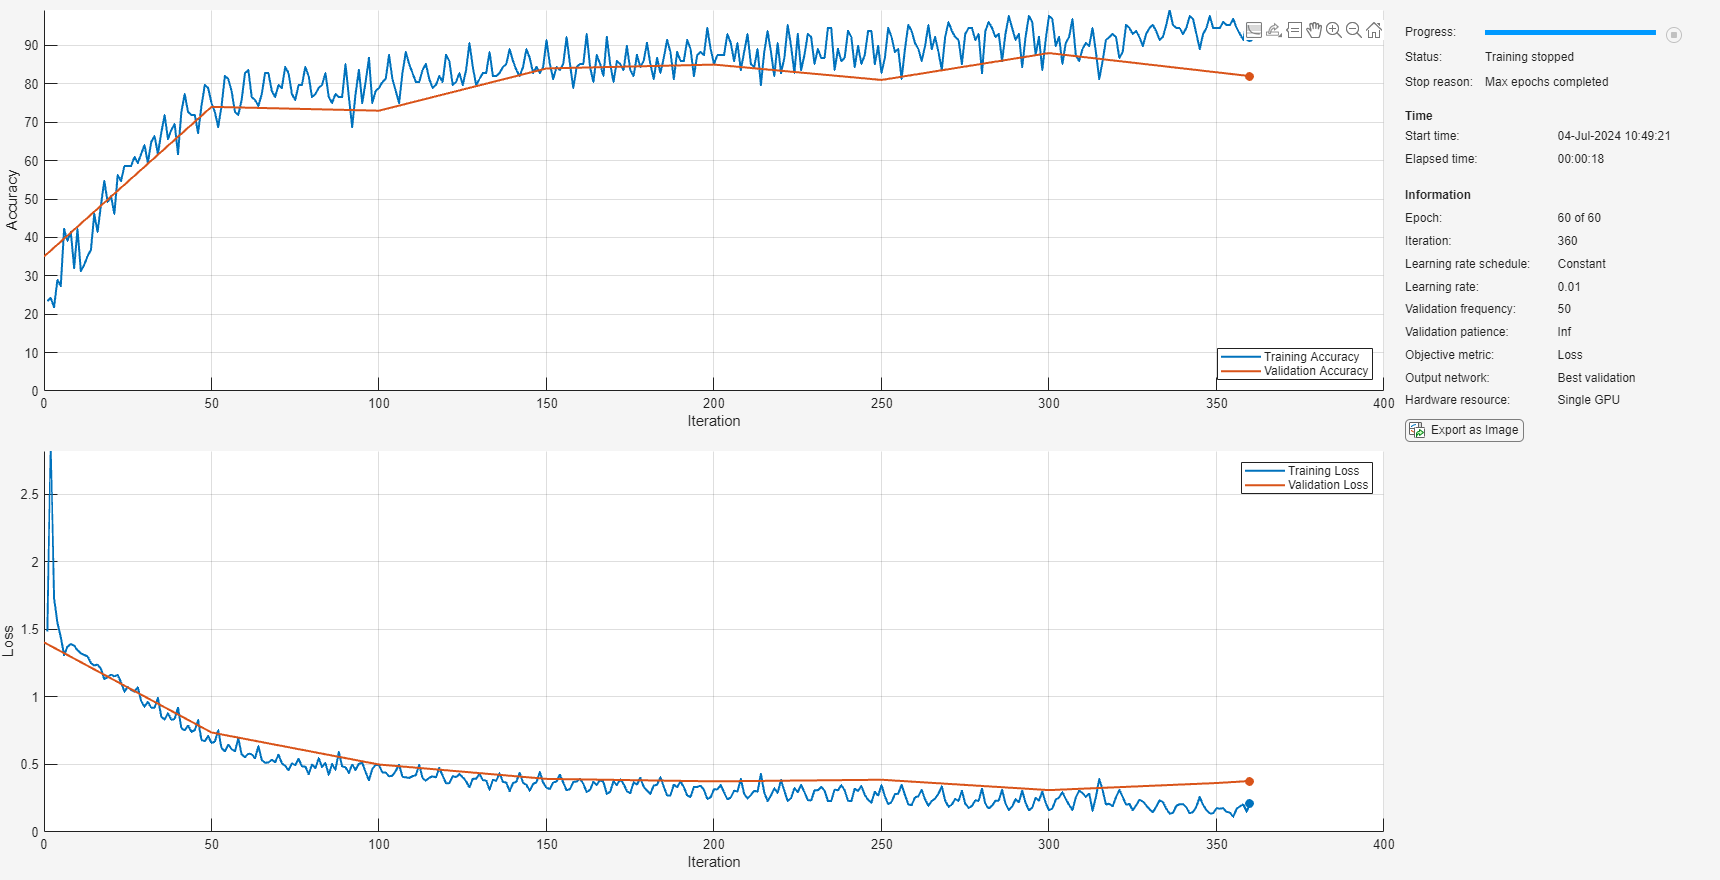

net = trainnet(XTrain,TTrain,layers,"crossentropy",options);

## Test Neural Network

Classify the test data using the same sequence padding options used for training. To make predictions with multiple observations, use the `minibatchpredict` function. To convert the prediction scores to labels, use the `scores2label` function. The `minibatchpredict` function automatically uses a GPU if one is available. Using a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the function uses the CPU.

scores = minibatchpredict(net,XTest,SequencePaddingDirection="left");
YTest = scores2label(scores, classNames);

Calculate the classification accuracy of the predictions.

acc = mean(YTest == TTest)

acc = 0.8600

Visualize the predictions in a confusion matrix.

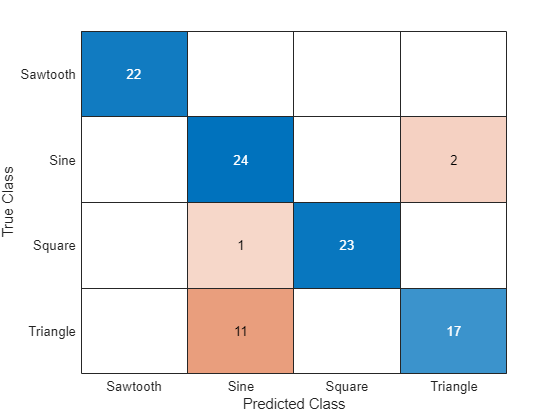

figure
confusionchart(TTest,YTest)

*Copyright 2021-2023 The MathWorks, Inc.*